clear
close
addpath(genpath('TRD_function\')); 

## set of parameters

lambda = 0.01; % regularization parameter
gamma1 = 0.8; % stepsize of PDS
gamma2 = 1/(8*gamma1);
maxIter = 5000; % max number of iterations
stopcri = 1e-5; % stopping criterion
r = [12,8,8];
epsilon = 1e-3;
disprate = 20;

## observation generation

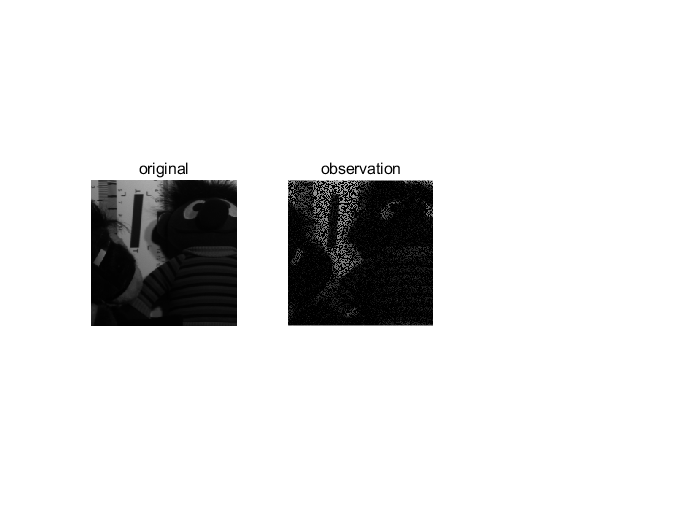

load Test

[rows, cols, bands] = size(O_Img);
N = rows*cols*bands;

% randam decimation operator
K = round(N/2); % decimation rate
I = randperm(N);
Phi = @(z) z(I(1:K))'; % decimation operator
Phit = @(z) deci_trans(z,I,K,rows,cols,bands);

sigma = 10/255; % noise standard deviation
v = Phi(O_Img/255) + sigma*randn(K,1); % observation (decimation+noise)
v = Phit(v);


figure(1);
subplot(1,3,1), imshow(O_Img(:,:,10)/255), title('original');
subplot(1,3,2), imshow(v(:,:,10)), title('observation');

## initialization

% variables
u = randn(size(v));
z = D(zeros(size(u)));
Omega = Phit(ones(K,1));
S = size(u);
G = TR_initcoreten(S,r);
PSNR = zeros(1,maxIter);
Iter = 0;

## main loop%%

for i = 1:maxIter
     
    Iter = Iter + 1;
    upre = u;
    %update G;
    
    G = TR_dec(G,u,Omega);
    g  = coreten2tr(G);

    % update u
    u = u - gamma1*(2*(u-g) + Dt(z));
    u=metric_proj(u,v,epsilon);
    
    % update z
    z = z + gamma2*D(2*u - upre);
    ztemp = z/gamma2;
    
    map=zeros(size(ztemp));
    for j=1:bands
        onemat = ones(rows, cols);
        thresh = ((sqrt(sum(ztemp(:,:,j,:).^2,4))).^(-1))*lambda/gamma2;
        thresh(thresh > 1) = 1;
        coef = (onemat - thresh);
        map(:,:,j,:)=cat(4,coef,coef) ;
    end
       ztemp = map.*ztemp;
    
    z = z - gamma2*ztemp;

    % stopping condition
    error = u-upre;
    error = sqrt(sum(error(:).^2,'all'))/sqrt(sum(u(:).^2,'all'));
    psnrval = psnr(u,O_Img/255,1);
    PSNR(i)=psnrval;
    i
    error
    
     if rem(i,disprate) == 0
         disp(['i = ', num2str(i), ' PSNR = ', num2str(psnrval,4), ' error = ', num2str(error,4)])
     end
    if error < stopcri
        break;
    end
    
end

i = 1

error = 5.8676

i = 2

error = 6.4487e-06

## result plot

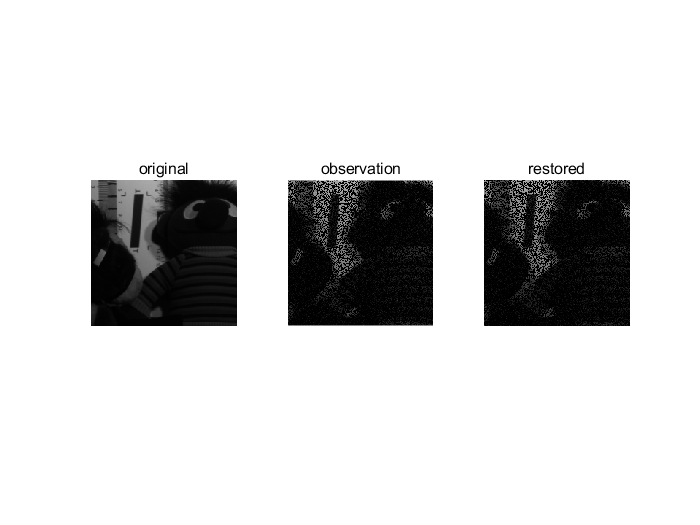

subplot(1,3,3), imshow(u(:,:,10)), title('restored');


PSNR

PSNR =    15.2315   15.2315         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


function y = D(x)
y=zeros([size(x),2]);
[rows,cols,bands]=size(x);
 for i=1:bands
     y(:,:,i,:)=cat(4, x([2:rows, 1],:,i) - x(:,:,i), x(:,[2:cols, 1],i)-x(:,:,i));     
 end
end

function y = Dt(x)
[rows,cols,bands,~]=size(x);
y=zeros(rows,cols,bands);
 for i=1:bands
     y(:,:,i)=[-x(1,:,i,1)+x(rows,:,i,1); - x(2:rows,:,i,1) + x(1:rows-1,:,i,1)] ...
    +[-x(:,1,i,2)+x(:,cols,i,2), - x(:,2:cols,i,2) + x(:,1:cols-1,i,2)];     
 end
end

function y = deci_trans(x,I,K,rows,cols,bands)
 y = zeros(rows,cols,bands);
 y(I(1:K)) = x;
end

function z = metric_proj(x,y,epsilon)
if(sqrt(sum((x-y).^2,'all'))<=epsilon)
    z=x;    
else
    z=y+(epsilon/sqrt(sum((x-y).^2,'all'))).*(x-y);
end
end